# Sample 13-1

## 辞書学習

カルーネン-レーベ変換（主成分分析）

画像処理特論

村松 正吾 

動作確認: MATLAB R2023a

## Dictionary learning

Karhunen–Loève transform (principle component analysis) 

Advanced Topics in Image Processing

Shogo MURAMATSU

Verified: MATLAB R2023a

### 準備

(Preparation)

clear 
close all
import msip.download_img
msip.download_img

kodim01.png already exists in ./data/
kodim02.png already exists in ./data/
kodim03.png already exists in ./data/
kodim04.png already exists in ./data/
kodim05.png already exists in ./data/
kodim06.png already exists in ./data/
kodim07.png already exists in ./data/
kodim08.png already exists in ./data/
kodim09.png already exists in ./data/
kodim10.png already exists in ./data/
kodim11.png already exists in ./data/
kodim12.png already exists in ./data/
kodim13.png already exists in ./data/
kodim14.png already exists in ./data/
kodim15.png already exists in ./data/
kodim16.png already exists in ./data/
kodim17.png already exists in ./data/
kodim18.png already exists in ./data/
kodim19.png already exists in ./data/
kodim20.png already exists in ./data/
kodim21.png already exists in ./data/
kodim22.png already exists in ./data/
kodim23.png already exists in ./data/
kodim24.png already exists in ./data/
See <a href="http://www.r0k.us/graphics/kodak/">Kodak Lossless True Color Image Suite</a

### パラメータ設定

(Parameter settings)

- ブロックサイズ (Block size)

szBlk = [ 8 8 ];

## 画像の読込

(Read image)

- 
$$\mathbf{u}\in\mathbb{R}^{N}$$


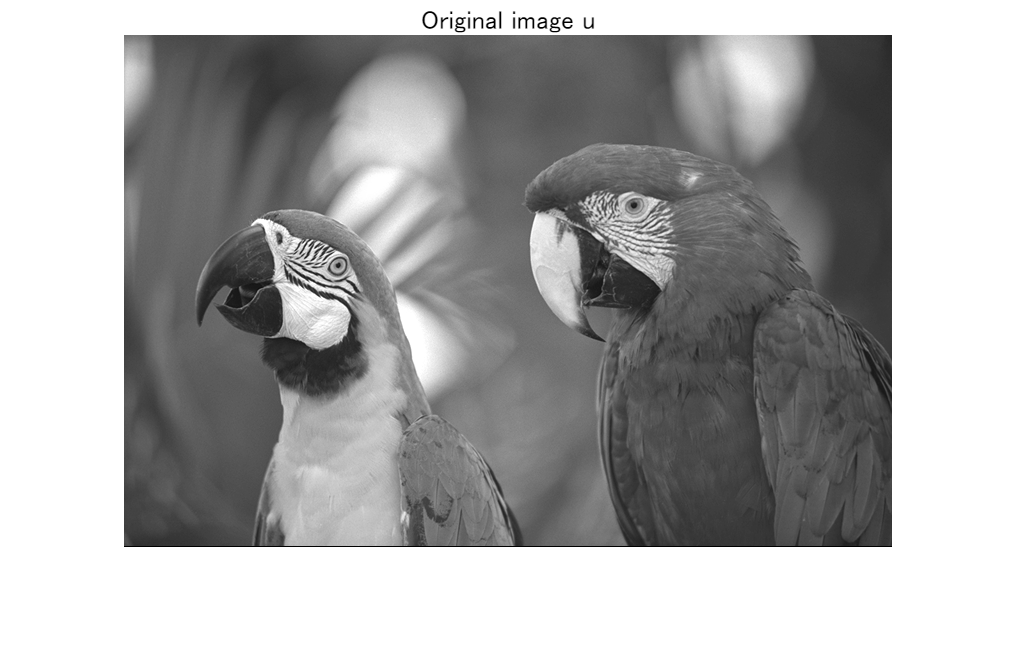

u = rgb2gray(im2double(imread('./data/kodim23.png')));
szOrg = size(u);
figure
imshow(u);
title('Original image u')

#### 画像 $\mathbf{y}$からのデータ行列 $\mathbf{Y}$ の生成 

(Generate data matrices from images )

標本平均ブロックを引く代わりに，予め零平均化したデータで学習(Instead of subtracting the sample average block, training with pre-zero averaged data)

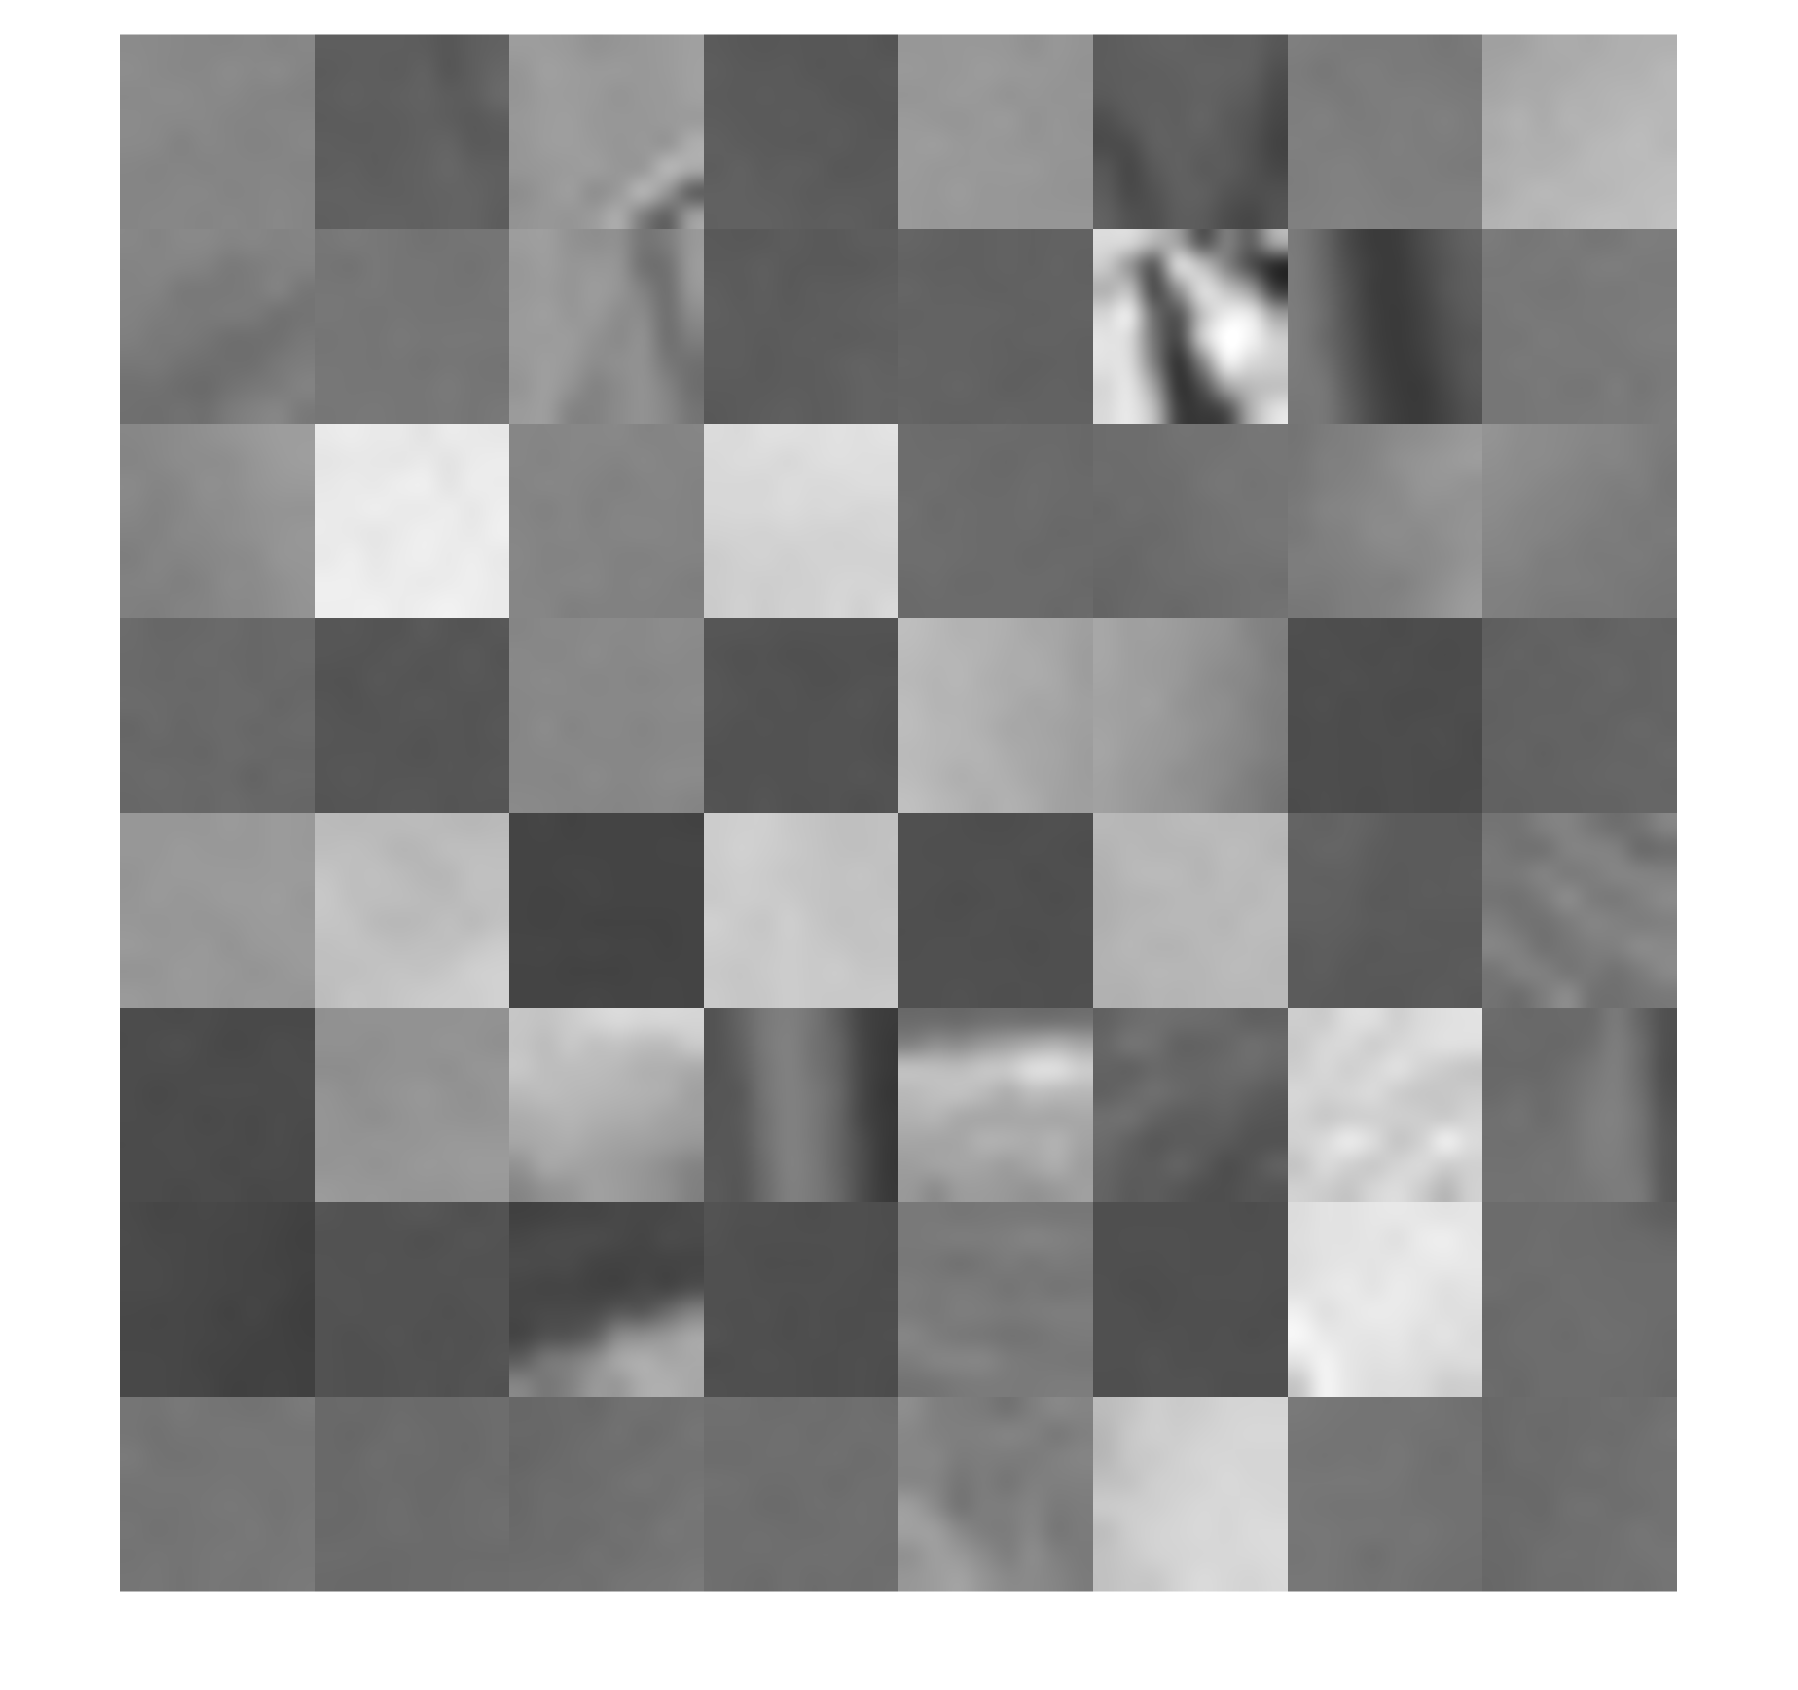

meansubtract = @(x) x-mean(x,"all");
y = meansubtract(u);

% # of patches
nPatches = prod(szOrg./szBlk); 

npos = randsample(prod(szOrg-szBlk),nPatches);
ybs = zeros(szBlk(1),szBlk(2),nPatches,'like',y);
szSrchy = szOrg(1)-szBlk(1);
for iPatch = 1:nPatches
    ny_ = mod(npos(iPatch)-1,szSrchy)+1;
    nx_ = floor((npos(iPatch)-1)/szSrchy)+1;
    ybs(:,:,iPatch) = y(ny_:ny_+szBlk(1)-1,nx_:nx_+szBlk(2)-1);
end
figure
montage(ybs+0.5,'Size',[8 8]);

drawnow

Y = reshape(ybs,prod(szBlk),[]);


## カルーネン-レーベ変換（主成分分析）

(Karhunen–Loève transform (principle component analysis))

#### 問題設定 (Problem setting):

        
$$\widehat{\mathbf{\Phi}}=\arg \max _{\mathbf{\Phi}\in\mathbb{R}^{M\times M}} \mathrm{tr}\left(\mathbf{\Phi}_{:, 1: p}^{T} \widehat{\mathbf{\Sigma}}_{y} \mathbf{\Phi}_{:, 1: p}\right), \text { s.t. } \mathbf{\Phi}^{T} \mathbf{\Phi}=\mathbf{I}_{M}, \forall p \in\{1,2, \cdots, M\}$$


ただし， $\widehat{\mathbf{\Sigma}}_{y}$は 観測ベクトル $\{\mathbf{y}_n\}_n$ （零平均を仮定）の標本分散共分散行列 (where， $\widehat{\mathbf{\Sigma}}_{y}$ is the sample covariance matrix of the observation vectors $\{\mathbf{y}_n\}_n$ (assumed to have zero mean:)

        
$$\widehat{\mathbf{\Sigma}}_{y}=\frac{1}{S-1}\sum_{n=1}^{S}\mathbf{y}_n\mathbf{y}_n^T$$


#### 解 (Solution):

固有値分解 (Eigendecomposition) 

        
$$\widehat{\mathbf{\Phi}}^T\widehat{\mathbf{\Sigma}_y}\widehat{\mathbf{\Phi}}=\mathbf{\Lambda}
$$


ただし， $\mathbf{\Lambda}=\mathrm{diag}(\lambda_1,\lambda_2,\cdots,\lambda_M)$． $\lambda_1\geq\lambda_2\geq\cdots\lambda_M$ は $\widehat{\mathbf{\Sigma}}_{y}$の固有値．(where,  $\mathbf{\Lambda}=\mathrm{diag}(\lambda_1,\lambda_2,\cdots,\lambda_M)$． $\lambda_1\geq\lambda_2\geq\cdots\lambda_M$ are the eigenvalues of $\widehat{\mathbf{\Sigma}}_{y}$.)

標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の計算 (Calculation of sample covariance matrix $\widehat{\mathbf{\Sigma}}_{y}$)

SigmaY = cov(Y.');

標本分散共分散行列 $\widehat{\mathbf{\Sigma}}_{y}$の固有値分解 (Eigendecomposition of sample covariance matrix  $\widehat{\mathbf{\Sigma}}_{y}$)

[Phi_pca,Lambda] = eig(SigmaY);

固有値 $\lambda$ の大きさの降順に列ベクトルをソート (Sorting column vectors in the descending order of the eigenvalues $\lambda$)

[~,idx] = sort(diag(Lambda),'descend');
Phi_pca = Phi_pca(:,idx);

固有ベクトルを基底画像に変換 (Reshape the eigenvectures into basis images)

nBases = prod(szBlk);
basisImagesPca = zeros(szBlk(1),szBlk(2),nBases);
for iBasis = 1:nBases
    basisImagesPca(:,:,iBasis) = reshape(Phi_pca(:,iBasis),szBlk(1),szBlk(2));
end

#### 基底画像の表示

(Show basis images)

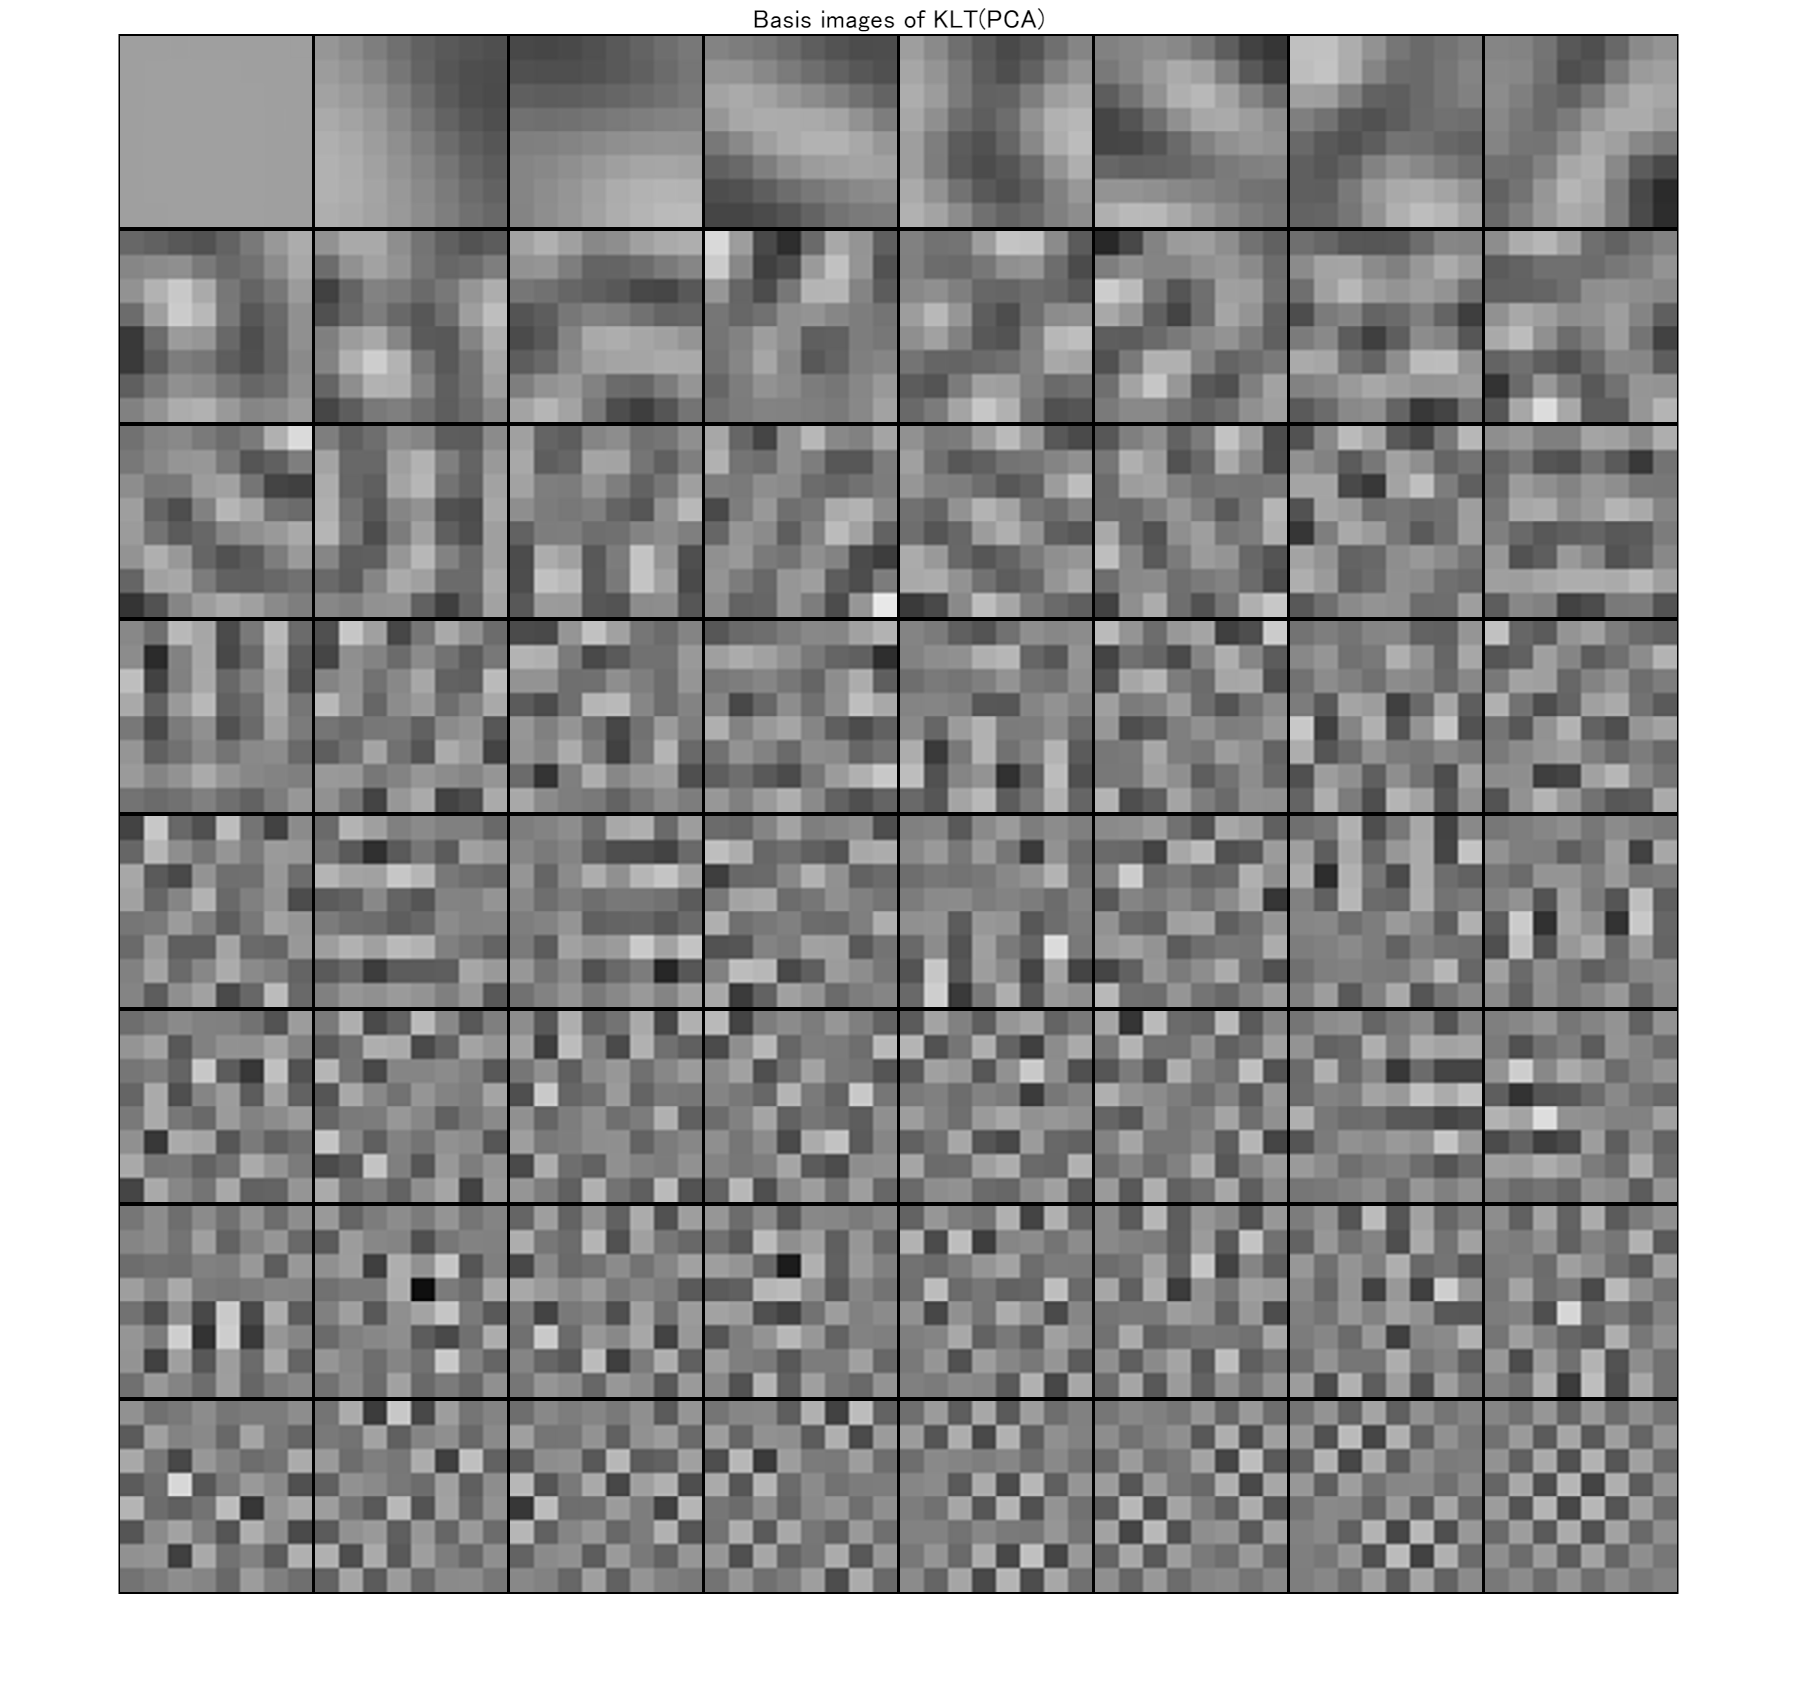

figure
montage(imresize(basisImagesPca,8,'nearest')+.5,'BorderSize',[2 2])
title('Basis images of KLT(PCA)')

#### ブロックPCAによる合成処理とその随伴処理の定義

(Definition of synthesis process and its adjoint process by block PCA)

syn_blkpca = @(x) col2im(Phi_pca*x,szBlk,szOrg,"distinct");
adj_blkpca = @(y) Phi_pca.'*im2col(y,szBlk,"distinct");

随伴関係の確認(Confirmation of adjoint relationship)

x = adj_blkpca(y);
v = randn(size(x));
u = syn_blkpca(v);
assert(abs(dot(y(:),u(:))-dot(x(:),v(:)))<1e-9)

© Copyright, 2018-2023, Shogo MURAMATSU, All rights reserved.